## 平均音速の線形的変化に対する誤差の評価・集計

筋肉層，脂肪層，筋肉層の３層構造を考えた．

layered_medium_SART_ROI_10mm_horizontal.m

layered_medium_SART_ROI_10mm_vertical.m

を用いて結果を比較する．

clear; 
load('2018_04_03_layered_medium_SART_ROI_10mm_horizontal.mat');

layered_medium_SART_ROI_10mm_horizontal.matを呼び出す

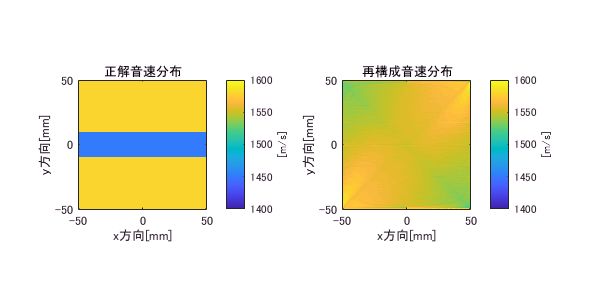

figure;
subplot(1,2,1);
[ Medium, Layer ] = make_layered_medium_horizontal( 10, Grid );
imagesc(Grid.x*1000,Grid.y*1000,Medium.sound_speed);
colorbar
c = colorbar;
c.Label.String = '[m/s]';
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
title('正解音速分布')
caxis([1400 1600])
axis equal
axis tight

subplot(1,2,2);
imagesc(Grid.x*1000,Grid.y*1000,us(:,:,30,10));
colorbar
c = colorbar;
c.Label.String = '[m/s]';
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
title('再構成音速分布')
caxis([1400 1600])
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
exportfig('2018_04_10_SART_horizontal_10mm','png',[600,300]);

SARTを３０回繰りかえした，横方向に分布する厚み10 mmの脂肪層についての音速再構成．脂肪層がほとんど経路に対して直交しているために，深さ方向でどのあたりに分布しているかを反映するような情報が含まれていない．

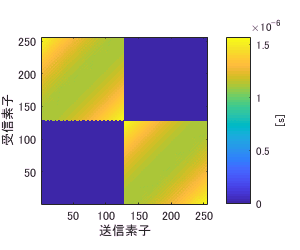

figure;
imagesc(projection);
colorbar
c = colorbar;
c.Label.String = '[s]';
set(gca,'YDir','normal');
xlabel('送信素子')
ylabel('受信素子')
axis tight
axis equal
exportfig('2018_04_10_SART_horizontal_10mm_TOF','png',[300,250]);

投影データを見ても，情報にコントラストがついておらず，情報量が少ないことがわかる．

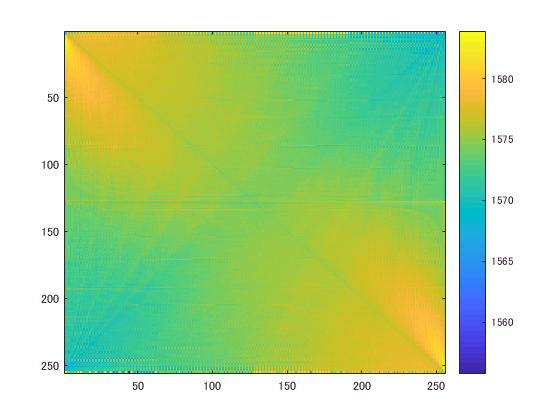

figure;
imagesc(us(:,:,30,2));
colorbar;

SARTを３０回繰りかえした，横方向に分布する厚み2 mmの脂肪層についての音速再構成．2, 4, 6, 8, 10 mmと脂肪層の厚みを変化させている．その中で，2, 10 mmのデータの端点となるものを表示した．

投影データはmatデータには含まれておらず，layered_medium_SART_ROI_10mm_horizontal.mを再度部分的に動かして取得する．この時点では表示しない（2018-04-09）

続いて，ROIを設定する．あとで関数化したりスクリプトに起こすことも踏まえたコードを書く．

描写領域の中央とROIの中心は一致している．ROIは10 x 10 [mm2]の正方領域である．

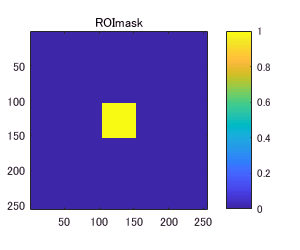

indROI.x = (abs(Grid.x) <= 10.e-3);%ROIのxにおける範囲に相当する引数
indROI.y = (abs(Grid.y) <= 10.e-3);%ROIのyにおける範囲に相当する引数
indROI.grid = indROI.y .* indROI.x.';%ROI領域を示す論理型数値
figure;imagesc(indROI.grid);%indROI.gridを描写
colorbar;
axis tight
axis equal
title('ROImask');
exportfig('2018_04_10_SART_horizontal_ROImask','png',[300,250]);

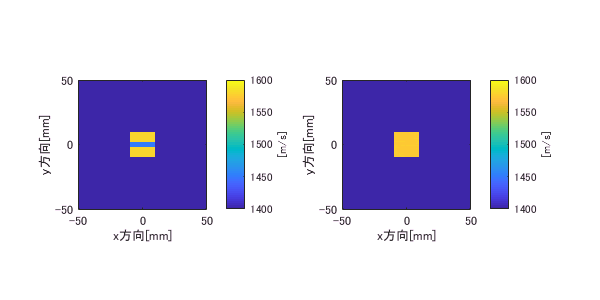

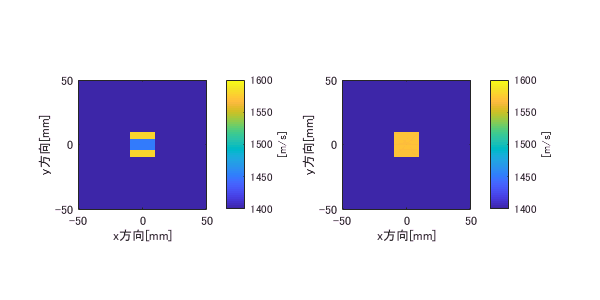

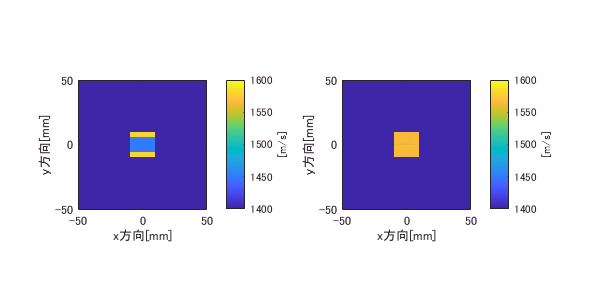

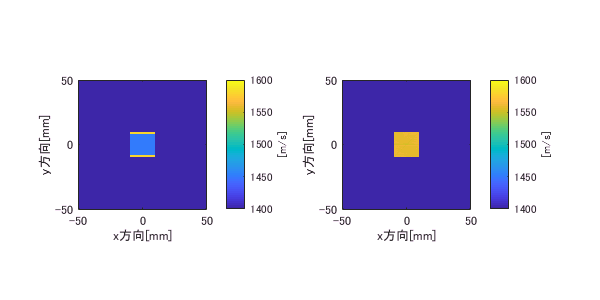

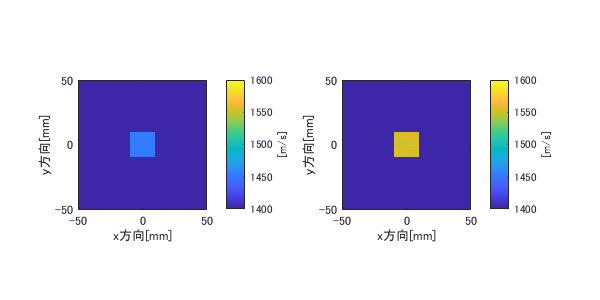


[a,b] = size(indROI.grid);
ROI.recon = zeros(a,b,thickness_Max/2);
ROI.true = zeros(a,b,thickness_Max/2);
for thicknessHalf = 1:thickness_Max/2
    [ Medium, Layer ] = make_layered_medium_horizontal( thicknessHalf*2, Grid );
    ROI.true(:,:,thicknessHalf) = Medium.sound_speed .* indROI.grid;%ROI中の正解音速分布
    ROI.recon(:,:,thicknessHalf) = us(:,:,30,thicknessHalf*2) .* indROI.grid;%ROI中の再構成音速分布
    figure;
    subplot(1,2,1);imagesc(Grid.y*1e3,Grid.x*1e3,ROI.true(:,:,thicknessHalf));
    colorbar;axis equal;axis tight;
    caxis([1400 1600])
    set(gca,'YDir','normal');
    xlabel('x方向[mm]');
    ylabel('y方向[mm]');
    c = colorbar;
    c.Label.String = '[m/s]';
    subplot(1,2,2);imagesc(Grid.y*1e3,Grid.x*1e3,ROI.recon(:,:,thicknessHalf));
    colorbar;axis equal;axis tight;
    caxis([1400 1600])
    set(gca,'YDir','normal');
    xlabel('x方向[mm]');
    ylabel('y方向[mm]');
    c = colorbar;
    c.Label.String = '[m/s]';
    exportfig(['2018_04_10_SART_horizontal_' num2str(thicknessHalf*2) 'mm_ROI'],'png',[600,300]);
end

左：正解音速分布，右：再構成音速分布

右はほとんど層の形状を反映していない．

ROI中の平均音速を正解・再構成において比較する．

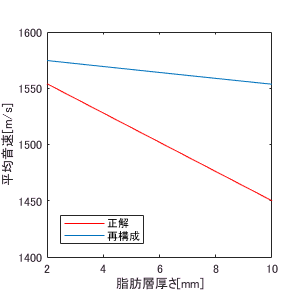

ROI.aveTrue = zeros(1,thickness_Max/2);%ROI中の平均音速（正解）
ROI.aveRecon = zeros(1,thickness_Max/2);%ROI中の平均音速（再構成）
count.ROI = sum(sum(indROI.grid));
for thicknessHalf = 1:thickness_Max/2
    ROI.aveTrue(thicknessHalf) = sum(sum(ROI.true(:,:,thicknessHalf))) / count.ROI;
    ROI.aveRecon(thicknessHalf) = sum(sum(ROI.recon(:,:,thicknessHalf))) / count.ROI;
end
figure;
plot(thickness_Min:2:thickness_Max,ROI.aveTrue,'r');
hold on
plot(thickness_Min:2:thickness_Max,ROI.aveRecon);
hold off
xlabel('脂肪層厚さ[mm]')
ylabel('平均音速[m/s]')
legend('正解','再構成','Location','southwest')
axis tight
axis square
ylim([1400 1600])
exportfig(['2018_04_10_SART_horizontal_SOS_Ave_ROI'],'png',[300,300]);

経路に対して直行する３層構造については正確度が低いといえる．

% save('layered_medium_SART_ROI_10mm_horizontal_after_analyze.mat');

続いて，layered_medium_SART_ROI_10mm_vertical.mで同様の検証を行う．

clear; 
load('2018_04_09_layered_medium_SART_ROI_10mm_vertical.mat');

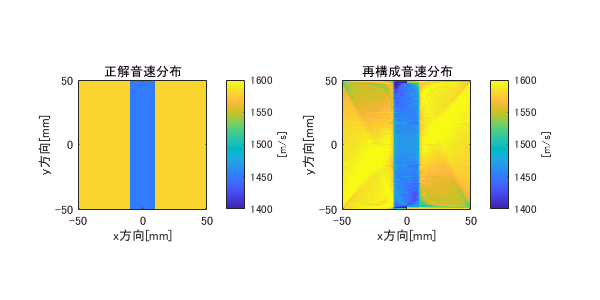

figure;
subplot(1,2,1);
[ Medium, Layer ] = make_layered_medium_vertical( 10, Grid );
imagesc(Grid.x*1000,Grid.y*1000,Medium.sound_speed);
colorbar
c = colorbar;
c.Label.String = '[m/s]';
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
title('正解音速分布')
caxis([1400 1600])
axis equal
axis tight

subplot(1,2,2);
imagesc(Grid.x*1000,Grid.y*1000,us(:,:,30,10));
colorbar
c = colorbar;
c.Label.String = '[m/s]';
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
title('再構成音速分布')
caxis([1400 1600])
set(gca,'YDir','normal');
xlabel('x方向[mm]')
ylabel('y方向[mm]')
axis equal
axis tight
exportfig('2018_04_10_SART_vertical_10mm','png',[600,300]);

SARTを３０回繰りかえした，縦方向に分布する厚み10 mmの脂肪層についての音速再構成．脂肪層がほとんど経路に対して平行しているために，深さ方向でどのあたりに分布しているかを反映するような情報が多く含まれている．

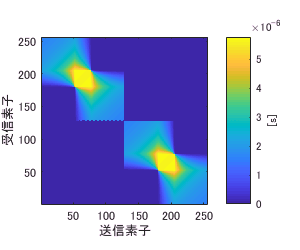

figure;
imagesc(projection);
colorbar
c = colorbar;
c.Label.String = '[s]';
set(gca,'YDir','normal');
xlabel('送信素子')
ylabel('受信素子')
axis tight
axis equal
exportfig('2018_04_10_SART_vertical_10mm_TOF','png',[300,250]);

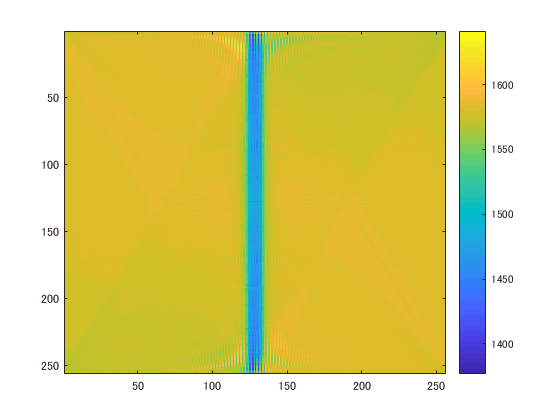

figure;
imagesc(us(:,:,30,2));
colorbar;

indROI.x = (abs(Grid.x) <= 10.e-3);%ROIのxにおける範囲に相当する引数
indROI.y = (abs(Grid.y) <= 10.e-3);%ROIのyにおける範囲に相当する引数
indROI.grid = indROI.y .* indROI.x.';%ROI領域を示す論理型数値
figure;imagesc(indROI.grid);%indROI.gridを描写
colorbar;
axis tight
axis equal
title('ROImask');
exportfig('2018_04_10_SART_vertical_ROImask','png',[300,250]);

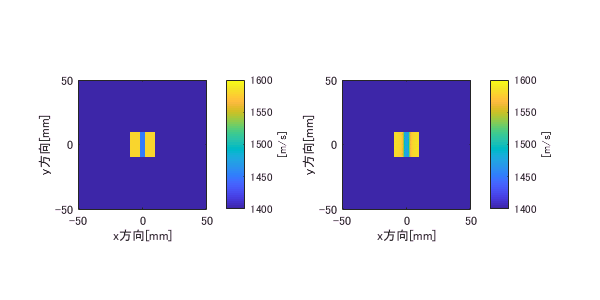

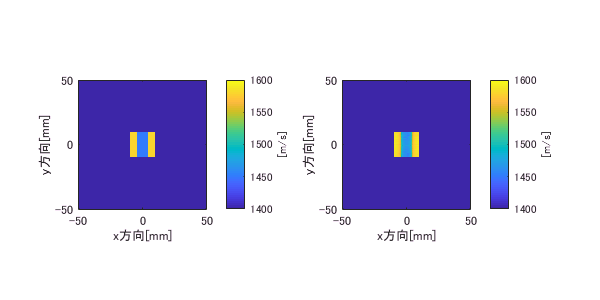

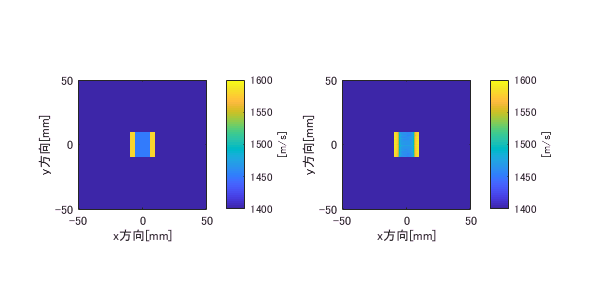

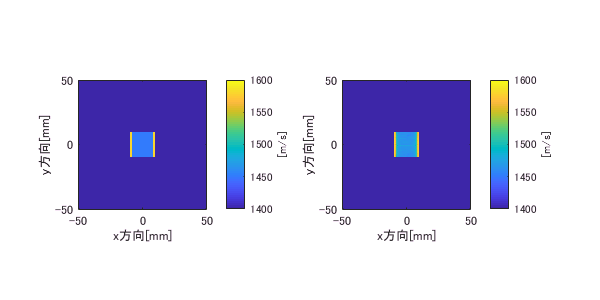

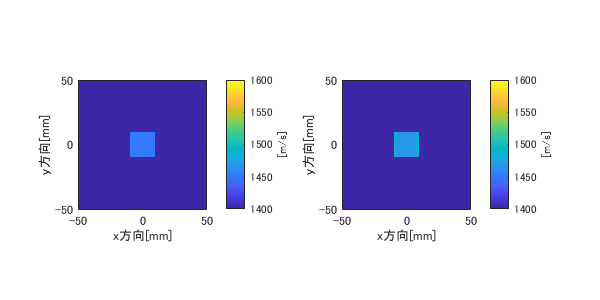


[a,b] = size(indROI.grid);
ROI.recon = zeros(a,b,thickness_Max/2);
ROI.true = zeros(a,b,thickness_Max/2);
for thicknessHalf = 1:thickness_Max/2
    [ Medium, Layer ] = make_layered_medium_vertical( thicknessHalf*2, Grid );
    ROI.true(:,:,thicknessHalf) = Medium.sound_speed .* indROI.grid;%ROI中の正解音速分布
    ROI.recon(:,:,thicknessHalf) = us(:,:,30,thicknessHalf*2) .* indROI.grid;%ROI中の再構成音速分布
    figure;
    subplot(1,2,1);imagesc(Grid.y*1e3,Grid.x*1e3,ROI.true(:,:,thicknessHalf));
    colorbar;axis equal;axis tight;
    caxis([1400 1600])
    set(gca,'YDir','normal');
    xlabel('x方向[mm]');
    ylabel('y方向[mm]');
    c = colorbar;
    c.Label.String = '[m/s]';
    subplot(1,2,2);imagesc(Grid.y*1e3,Grid.x*1e3,ROI.recon(:,:,thicknessHalf));
    colorbar;axis equal;axis tight;
    caxis([1400 1600])
    set(gca,'YDir','normal');
    xlabel('x方向[mm]');
    ylabel('y方向[mm]');
    c = colorbar;
    c.Label.String = '[m/s]';
    exportfig(['2018_04_10_SART_vertical_' num2str(thicknessHalf*2) 'mm_ROI'],'png',[600,300]);
end

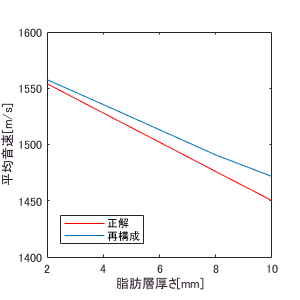

ROI.aveTrue = zeros(1,thickness_Max/2);%ROI中の平均音速（正解）
ROI.aveRecon = zeros(1,thickness_Max/2);%ROI中の平均音速（再構成）
count.ROI = sum(sum(indROI.grid));
for thicknessHalf = 1:thickness_Max/2
    ROI.aveTrue(thicknessHalf) = sum(sum(ROI.true(:,:,thicknessHalf))) / count.ROI;
    ROI.aveRecon(thicknessHalf) = sum(sum(ROI.recon(:,:,thicknessHalf))) / count.ROI;
end
figure;
plot(thickness_Min:2:thickness_Max,ROI.aveTrue,'r');
hold on
plot(thickness_Min:2:thickness_Max,ROI.aveRecon);
hold off
xlabel('脂肪層厚さ[mm]')
ylabel('平均音速[m/s]')
legend('正解','再構成','Location','southwest')
axis tight
axis square
ylim([1400 1600])
exportfig(['2018_04_10_SART_vertical_SOS_Ave_ROI'],'png',[300,300]);

経路に対して平行な３層構造については正確度が低いといえる．

図表を見やすくする（2018/04/09）

図表を整理した（2018/04/10）

save('2018_04_10_layered_medium_SART_ROI_10mm_vertical_after_analyze.mat');